Compute the price of an European call option using GBM and the

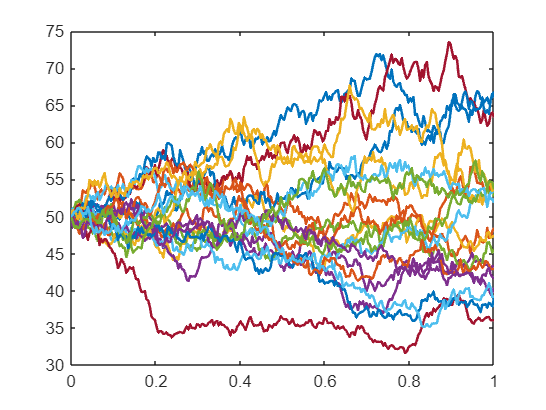

S0 = 50; % Initial stock price
K = 50; % Strike price
r = 0.05; % Risk-free interest rate (5%)
T = 1; % Time to maturity (1 year)
sigma = 0.2; % Volatility (20%)
N = 252; % Number of time steps (daily steps for one year)
M = 10000; % Number of simulated paths
dt = T / N; % Time step

    for j = 1:M
        dW = sqrt(dt) * randn(N, 1);
        S(1, j) = S0;

        for t = 1:N
            S(t+1, j) = S(t, j) * exp((r - 0.5 * sigma^2) * dt + sigma * dW(t));
        end
    end
    plot(0:dt:T, S(:, 1:20), 'LineWidth', 1.5);


    for j = 1:M
        payoff(j) = max(S(end, j) - K, 0);
    end

disc_payoffs = exp(-r * T) * payoff;
call_price = mean(disc_payoffs)

call_price = 5.0923

Compute the price of an European call option with Black-Scholes

S0 = 50; % Initial stock price
K = 50; % Strike price
r = 0.05; % Risk-free interest rate (5%)
T = 1; % Time to maturity (1 year)
sigma = 0.2; % Volatility (20%)
N = 252; % Number of time steps (daily steps for one year)
M = 10000; % Number of simulated paths
dt = T / N; % Time step

d1 = (log(S0/K) + (r + sigma^2/2)*T) / (sigma*sqrt(T));
d2 = d1 - sigma*sqrt(T);
N_d1 = normcdf(d1);
N_d2 = normcdf(d2);
call_price_bs = S0 * N_d1 - K * exp(-r * T) * N_d2

call_price_bs = 5.2253

Price a butterfly spread 

clear all
close all
S0 = 100; % Initial stock price
K1 = 90; % Lower strike price
K2 = 100; % Middle strike price
K3 = 110; % Higher strike price
r = 0.05; % Risk-free interest rate (5%)
T = 1; % Time to maturity (1 year)
sigma = 0.2; % Volatility (20%)
N = 252; % Number of time steps (daily steps for one year)
M = 10000; % Number of simulated paths
dt = T / N; % Time step

    for j = 1:M
        dW = sqrt(dt) * randn(N, 1);
        S(1,j) = S0;
        for t = 1:N
            S(t+1, j) = S(t, j) * exp((r - 0.5 * sigma^2) * dt + sigma * dW(t));
        end
    end

    for j = 1:M
        payoffK1(j) = max(S(end, j) - K1, 0);
        payoffK2(j) = max(S(end, j) - K2, 0);
        payoffK3(j) = max(S(end, j) - K3, 0);
    end

payoff = payoffK1 - 2 * payoffK2 + payoffK3;
disc_payoff = exp(-r * T) * payoff;
butterfly_price = mean(disc_payoff)

butterfly_price = 1.8564

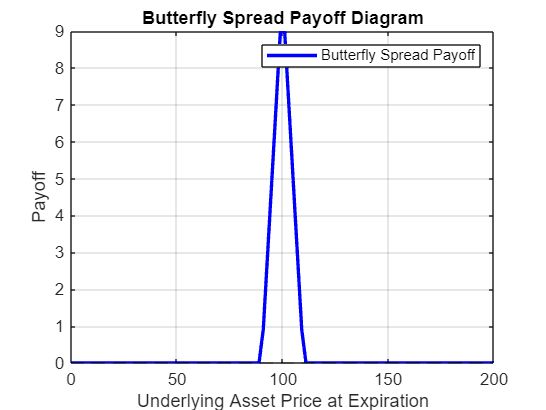



S_range = linspace(0, 2*S0, 100); % Range of underlying asset prices
payoff_range = max(S_range - K1, 0) - 2 * max(S_range - K2, 0) + max(S_range - K3, 0);

figure;
plot(S_range, payoff_range, 'b-', 'LineWidth', 2);
hold on;
yline(0, 'k--'); % Horizontal line at y=0 for reference
xlabel('Underlying Asset Price at Expiration');
ylabel('Payoff');
title('Butterfly Spread Payoff Diagram');
legend('Butterfly Spread Payoff');
grid on;
hold off;